**Upload Data**

folder = fullfile('C:', 'Users', 'compl', 'Documents', 'GitHub', 'PHY294-ThermalMotion', 'good_data');
files = dir(folder);

% lol
fileNames = {
    'trial8bottomleft.txt','trial8bottomright.txt', 'trial8left.txt', ...
    'trial9bottom.txt', 'trial9left.txt', ...
    'trial9secondtoright.txt', 'trial9topright.txt', 'trial10bottom.txt', ...
    'trial12mostright.txt', 'trial12top.txt'};

% Extract file names
% fileNames = {files(~[files.isdir]).name}; % Exclude directories
% fileNames = sprintf('fileNames = {\n    ''%s''\n};', strjoin(fileNames, ''', '''));
% disp(fileNames);

fileNames = {
    'test1-1.txt', 'test1-3.txt', 'test1-5.txt', 'test10-1.txt', 'test10-2.txt', 'test10-3.txt', 'test10-4.txt', 'test10-5.txt', 'test11-1.txt', 'test11-2.txt', 'test11-3.txt', 'test12-1.txt', 'test12-2.txt', 'test12-3.txt', 'test12-4.txt', 'test2-1.txt', 'test2-2.txt', 'test2-3.txt', 'test2-8.txt', 'test2-9.txt', 'test3-1.txt', 'test3-2.txt', 'test3-3.txt', 'test3-5.txt', 'test3-6.txt', 'test3-9.txt', 'test4-1.txt', 'test4-10.txt', 'test4-3.txt', 'test4-4.txt', 'test4-6.txt', 'test4-7.txt', 'test4-8.txt', 'test4-9.txt', 'test5-1.txt', 'test5-10.txt', 'test5-2.txt', 'test5-3.txt', 'test5-5.txt', 'test5-6.txt', 'test5-9.txt', 'test6-1.txt', 'test6-2.txt', 'test6-3.txt', 'test6-4.txt', 'test7-1.txt', 'test7-2.txt', 'test8-1.txt', 'test9-1.txt', 'test9-2.txt'
};


**Base Settings**

ptm = 0.12048; % microns per pixel
dt = 0.5; % time interval [s]
% Define an array of colors for each trial
colors = [
    1, 0, 0;  % Red
    1, 1, 1;  % Black
    0, 0, 1;  % Blue
    0, 1, 1;  % Cyan
    1, 0, 1;  % Magenta
    1, 1, 0;  % Yellow
    0.5, 0.5, 0.5;  % Gray
    0.5, 0, 0.5;    % Purple
    0, 0.5, 0.5;    % Teal
    0.5, 0.5, 0      % Olive
];

% Initialize cell arrays to store cumulative squared distances & slopes
cumulative_distances = cell(1, length(fileNames)); 
slopes = zeros(1, length(fileNames)); % Array to store slope for each trial
all_step_distances = [];
residuals = zeros(119,length(fileNames)); % Store residuals for each trial

**Loop over each file and calculate squared distance traveled as a function of time**

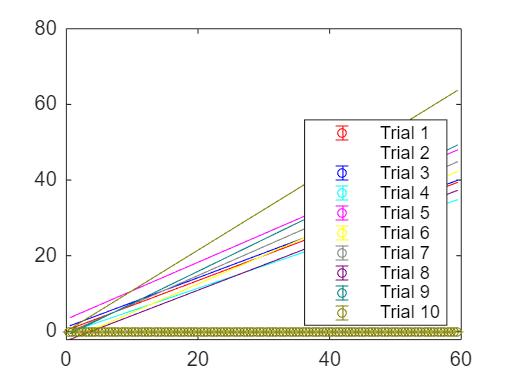

Trial = 1


Slope (m) = 6.5796e-13 ± 3.8344e-15


Intercept (b) = 2.7123e-13 ± 1.3255e-13


R² = 0.99604


Chi-Squared = 1509.6934


Reduced Chi-Squared = 12.9034


Trial = 2


Slope (m) = 8.7832e-13 ± 4.6979e-15


Intercept (b) = 3.9071e-13 ± 1.624e-13


R² = 0.99666


Chi-Squared = 2266.1738


Reduced Chi-Squared = 19.369


Trial = 3


Slope (m) = 6.531e-13 ± 4.5108e-15


Intercept (b) = 1.1133e-12 ± 1.5593e-13


R² = 0.99445


Chi-Squared = 2089.2946


Reduced Chi-Squared = 17.8572


Trial = 4


Slope (m) = 5.9358e-13 ± 5.0509e-15


Intercept (b) = -4.8575e-13 ± 1.746e-13


R² = 0.9916


Chi-Squared = 2619.619


Reduced Chi-Squared = 22.3899


Trial = 5


Slope (m) = 7.5337e-13 ± 6.6488e-15


Intercept (b) = 3.1886e-12 ± 2.2984e-13


R² = 0.99097


Chi-Squared = 4539.1677


Reduced Chi-Squared = 38.7963


Trial = 6


Slope (m) = 7.5496e-13 ± 7.9029e-15


Intercept (b) = -2.5832e-12 ± 2.7319e-13


R² = 0.98734


Chi-Squared = 6413.0693


Reduced Chi-Squared = 54.8126


Trial = 7


Slope (m) = 7.6283e-13 ± 5.1656e-15


Intercept (b) = -5.0955e-13 ± 1.7857e-13


R² = 0.99466


Chi-Squared = 2739.8619


Reduced Chi-Squared = 23.4176


Trial = 8


Slope (m) = 6.6954e-13 ± 7.4139e-15


Intercept (b) = -2.5215e-12 ± 2.5629e-13


R² = 0.98586


Chi-Squared = 5643.9769


Reduced Chi-Squared = 48.2391


Trial = 9


Slope (m) = 8.4729e-13 ± 4.8878e-15


Intercept (b) = -1.0876e-12 ± 1.6896e-13


R² = 0.99612


Chi-Squared = 2453.1171


Reduced Chi-Squared = 20.9668


Trial = 10


Slope (m) = 1.0713e-12 ± 8.5752e-15


Intercept (b) = 3.8308e-14 ± 2.9644e-13


R² = 0.99256


Chi-Squared = 7550.7034


Reduced Chi-Squared = 64.5359


Trial = 11


Slope (m) = 6.8489e-13 ± 6.7176e-15


Intercept (b) = 9.3239e-13 ± 2.3222e-13


R² = 0.98887


Chi-Squared = 4633.5839


Reduced Chi-Squared = 39.6033


Index in position 1 exceeds array bounds. Index must not exceed 10.

figure;
for k = 1:length(fileNames)
    % Load data
    filename = fullfile(folder, fileNames{k});
    opts = detectImportOptions(filename, 'NumHeaderLines', 2); 
    data = readtable(filename, opts);
    x = data{:, 1} * ptm; % unit conversion
    y = data{:, 2} * ptm; 

    % Calculate r^2 & r for each step
    dx = diff(x);
    dy = diff(y);
    r_squared = (dx.^2 + dy.^2) * 1e-12;
    r = sqrt(r_squared); 

    % Define time vector based on length of r_squared
    time_vector = (1:length(r_squared)) * dt; 
    
    % Cumulative squared distance for MSD
    cumulative_distances{k} = cumsum(r_squared);
    all_step_distances = [all_step_distances, r'];  % Concatenate step distances for histogram (r' = transpose r, column to row vector)

    %%% Linear Regression
    xlin = time_vector';
    ylin = (cumulative_distances{k});
    dy = repmat(0.2e-12, 1, length(time_vector))';

    % Number of measurements
    N = length(xlin);

    % Calculate sums needed for the formulas
    Sx = sum(xlin);
    Sy = sum(ylin);
    Sxy = sum(xlin .* ylin);
    Sxx = sum(xlin .* xlin);
    Syy = sum(ylin .* ylin);

    % Calculate the determinant delta (∆)
    delta = N * Sxx - Sx^2;

    % Calculate slope (m) and intercept (b)
    m = (N * Sxy - Sx * Sy) / delta;
    slopes(k) = m;
    b = (Sxx * Sy - Sx * Sxy) / delta;
    yintercepts(k) = b;

    % Calculate the variance of y(x)
    y_fit = m * xlin + b;
    variance = sum((ylin - y_fit).^2) / (N - 2);
    residuals(:,k) = ylin - y_fit;

    % Calculate the standard deviation of the slope (sm) and intercept (sb)
    sm = sqrt(N * variance / delta);
    sb = sqrt(Sxx * variance / delta);

    % Calculate R² (coefficient of determination)
    y_mean = mean(ylin);
    SStot = sum((ylin - y_mean).^2);  % Total sum of squares
    SSres = sum((ylin - y_fit).^2);    % Sum of squares of residuals
    R_squared = 1 - (SSres / SStot);

    % Reduced Chi-Squared Calculation
    chi_squared = sum(((ylin - y_fit).^2) ./ dy.^2);  % Chi-squared calculation
    reduced_chi_squared = chi_squared / (N - 2);   % Reduced chi-squared (N-2 degrees of freedom)

    % Display results
    disp(['Trial = ', num2str(k)]);
    disp(['Slope (m) = ', num2str(m), ' ± ', num2str(sm)]);
    disp(['Intercept (b) = ', num2str(b), ' ± ', num2str(sb)]);
    disp(['R² = ', num2str(R_squared)]);
    disp(['Chi-Squared = ', num2str(chi_squared)]);
    disp(['Reduced Chi-Squared = ', num2str(reduced_chi_squared)]);

    %Plot MSD for each file
    legend('show','Location', 'southeast');
    errorbar(time_vector, cumulative_distances{k}, dy,'o', 'MarkerSize', 4, 'DisplayName', sprintf('Trial %d', k), 'Color', colors(k, :));
    hold on;
    lin_fit = slopes(k)/ 10e-13 .* time_vector + yintercepts(k)/ 10e-13;
    % Plot cumulative squared distance traveled for each file
    plot(time_vector, lin_fit, 'LineStyle', '-', 'Color', colors(k, :), 'HandleVisibility', 'off');
end

**Plot Average Linear Fit**

avg_fit = mean(slopes)/ 10e-12 .* time_vector + mean(yintercepts) / 10e-12;
plot(time_vector, avg_fit, 'LineWidth', 1.5, 'DisplayName', 'Average Linear Fit', 'Color', 'green', 'LineStyle', '-');
xlabel('Time (s)');
ylabel('Mean Squared Displacement (\mum^2)');
title('Mean Squared Displacement vs Time for Each Trial');
hold off;

**Plot Residuals**

figure;
hold on;
for k = 1:length(fileNames)
    scatter(time_vector, residuals(:,k), 'DisplayName', sprintf('Trial %d', k), 'Color', colors(k, :));
    plot(time_vector, residuals(:,k), 'HandleVisibility', 'off', 'Color', colors(k, :));
end
yline(0, 'r--', 'LineWidth', 1.5); % Reference line at zero
xlabel('Time (s)');
ylabel('Residuals');
title('Residual Plot');
legend('show');
hold off;

% Calculate residual standard deviation
residual_std = std(residuals(:)); % Assuming residuals is a matrix or vector

% Define ±2 standard deviation thresholds
threshold_upper = 2 * residual_std;
threshold_lower = -2 * residual_std;

% Identify outliers
outliers = abs(residuals) > threshold_upper; % Logical array of outlier locations
num_outliers = sum(outliers(:)) % Total count of outliers

**Calculations for Part 1, Method 1: Eistein w fitted Drag Coefficient**

% Average slope, R^2, Reduced Chi-Squared
% Avg Drag Coefficient
D_Einstein = mean(slopes) / 4 %[m^2/s]D = slope / 4 for 2D diffusion
U_D_Einstein = D_Einstein * sqrt((mean(sm)/mean(slopes))^2 + (0.03/mean(time_vector))^2) %Uncertainty for D

% k
T = 296.5; %+/-0.1 Kelvin
r = 0.95 * 1e-6; %+/10^-7 meters (diamter/2, 1.95/2)
eta = 0.961 * 0.001; %Pa*s adjusted eta based off of 298K
gamma = 6 * pi * eta * r; %γ = 6πηr, η=8.9e-4, r=v1e-6
k_Einstein = D_Einstein * gamma / T
U_gamma = gamma * sqrt((0.05)^2+(0.1/1.9)^2)
U_k_Einstein = k_Einstein * sqrt((U_D_Einstein/D_Einstein)^2+(U_gamma/gamma)^2+(0.5/296.5)^2) % Uncertainty for k

%Difference between predicted 
Diff_k_Einstein = abs(1.38e-23 - k_Einstein)     
Diff_p_k_Einstein = Diff_k_Einstein / k_Einstein

% N_A
N_A_Einstein = 8.314/k_Einstein
U_N_A_Einstein = N_A_Einstein * U_k_Einstein / k_Einstein % Uncertainty for N_A

**Part 2: Method 2: Rayleigh w Fitted Histogram**

[h_counts, edges] = histcounts(all_step_distances * 1e-6, 'Normalization', 'pdf', 'NumBins', 50);  
bin_centers = edges(1:end-1) + diff(edges)/2;

Fit function to histogram data

fit_func = fittype('1/((4*3.14*D*t)^0.5) * exp(-r^2/(4*D*t))', 'independent', 'r', 'coefficients', {'D', 't'});
initial_D = 2.4509e-13; % Initial guess for D
initial_t = dt;      % Initial guess for t
%[fit_result, gof] = fit(bin_centers(:), h_counts(:), fit_func, 'StartPoint', [initial_D, initial_t]);

D_Histogram = fit_result.D

k_Histogram = D_Histogram * gamma / T
U_k_Histogram = k_Einstein * sqrt((U_D_Einstein/D_Einstein)^2+(U_gamma/gamma)^2+(0.5/296.5)^2)

Diff_k_Einstein = abs(1.38e-23 - k_Einstein)
Diff_p_k_Einstein = Diff_k_Einstein / k_Einstein
N_A_Histogram = 8.314 / k_Histogram


**Plot the histogram with the fitted Rayleigh distribution**

figure;
histogram(all_step_distances * 1e-6, 'Normalization', 'pdf', 'BinMethod', 'auto');
hold on;

% Overlay fitted Rayleigh distribution
r_values = linspace(min(bin_centers), max(bin_centers), 100); % Range of r values for fit
fitted_curve = feval(fit_result, r_values); % Evaluate the fitted Rayleigh function at r_values
plot(r_values, fitted_curve, 'r-', 'LineWidth', 2); % Plot the fitted curve

xlabel('Distance (m)');
ylabel('Probability Density');
title('Histogram of Step Distances with Rayleigh Fit');
legend('Histogram Data', 'Fitted Rayleigh Distribution');


**Part 2: Method 2: Max Likelihood w Fitted Histogram**

% Define the log-likelihood function for D
log_likelihood = @(D) -sum(log(all_step_distances * 1e-6 / (2 * D * dt)) - (all_step_distances * 1e-6).^2 / (4 * D * dt));

% Initial guess for D
initial_D = 2.4509e-13;

% Calculations
D_MLE = fminsearch(log_likelihood, initial_D)
k_MLE = D_MLE * gamma / T
N_A_MLE = 8.314 / k_MLE

max_likelihood_fitted = @(D) -sum(log(all_step_distances * 1e-6 / (2 * D * dt)) - (all_step_distances * 1e-6).^2 / (4 * D * dt));
% plot(r_values, max_likelihood_fitted, 'r-', 'LineWidth', 2); % Plot the fitted curve
hold off;

